# EECE 5644 Intro to Machine Learning Homework #2

## Question 1 (50%)

        The probability density function (pdf) for a 2-dimensional real-valued random vector $\textbf{X}$ is as follows: $p(\textbf{x}) = P(L=0)p(\textbf{x}|L=0) + P(L=1)p(\textbf{x}|L=1)$. Here $L$ is the true class label that indicates which class-label-conditioned pdf generates the data. 

        The class priors are $P\left(L=0\right)=0\ldotp 6\;\textrm{and}\;P\left(L=1\right)=0\ldotp 4$. The class class-conditional pdfs are $p(\textbf{x}|L=0) = w_1g(\textbf{x}|\textbf{m}_{01},\textbf{C}_{01}) + w_2g(\textbf{x}|\textbf{m}_{02},\textbf{C}_{02})$ and $p(\textbf{x}|L=1) = g(\textbf{x}|\textbf{m}_{1},\textbf{C}_{1})$, where $g(\textbf{x}|\textbf{m},\textbf{C})$ is a multivariate Gaussian probability density function with mean vector $\textbf{m}$ and covariance matrix $\textbf{C}
$. The parameters of the class-conditional Gaussian pdfs are: $w_1 = w_2 = 1/2,$ and


$$\textbf{m}_{01} = $$

$$\left\lbrack \begin{array}{c}
5\\
0
\end{array}\right\rbrack$$
 
$$\textbf{C}_{01} = $$

$$\left\lbrack \begin{array}{cc}
4 & 0\\
0 & 2
\end{array}\right\rbrack$$
 
$$\textbf{m}_{02} = $$

$$\left\lbrack \begin{array}{c}
0\\
4
\end{array}\right\rbrack$$

$$\textbf{C}_{02} = $$

$$\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 3
\end{array}\right\rbrack$$
 
$$\textbf{m}_{1} = $$

$$\left\lbrack \begin{array}{c}
3\\
2
\end{array}\right\rbrack$$
 
$$\textbf{C}_{1} = $$

$$\left\lbrack \begin{array}{cc}
2 & 0\\
0 & 2
\end{array}\right\rbrack$$


        For numerical results requested below, generate the following independent datasets each consisting of iid samples from the specified data distribution, and in each dataset make sure to include the true class label for each sample. Save the data and use the same data set in all subsequent exercises. 

- $D^{100}_{train}$ consists of $100$ samples and their labels for training:

- $D^{1000}_{train}$ consists of $1000$ samples and their labels for training:

- $D^{10K}_{train}$ consists of $10000$ samples and their labels for training:

- $D^{20K}_{validate}$ consists of $20000$ samples and their labels for training:

### Part 1: (10%) 

        Determine the theoretically optimal classifier that achieves minimum probability of error using the knowledge of the true pdf. Specify the classifier mathematically and implement it; then apply it to all samples in $D^{20K}_{validate}$ validate. From the decision results and true labels for this validation set, estimate and plot the ROC curve of this min-P(error) classifier, and on the ROC curve indicate, with a special marker, the point that corresponds to the min-P(error) classifier’s operating point. Also report your estimate of the min-P(error) achievable, based on counts of decision-truth label pairs on $D^{20K}_{validate}$.

**Optional**: As supplementary visualization, generate a plot of the decision boundary of this classification rule overlaid on the validation dataset. This establishes an aspirational performance level on this data for the following approximations.

### Generated Datasets: 

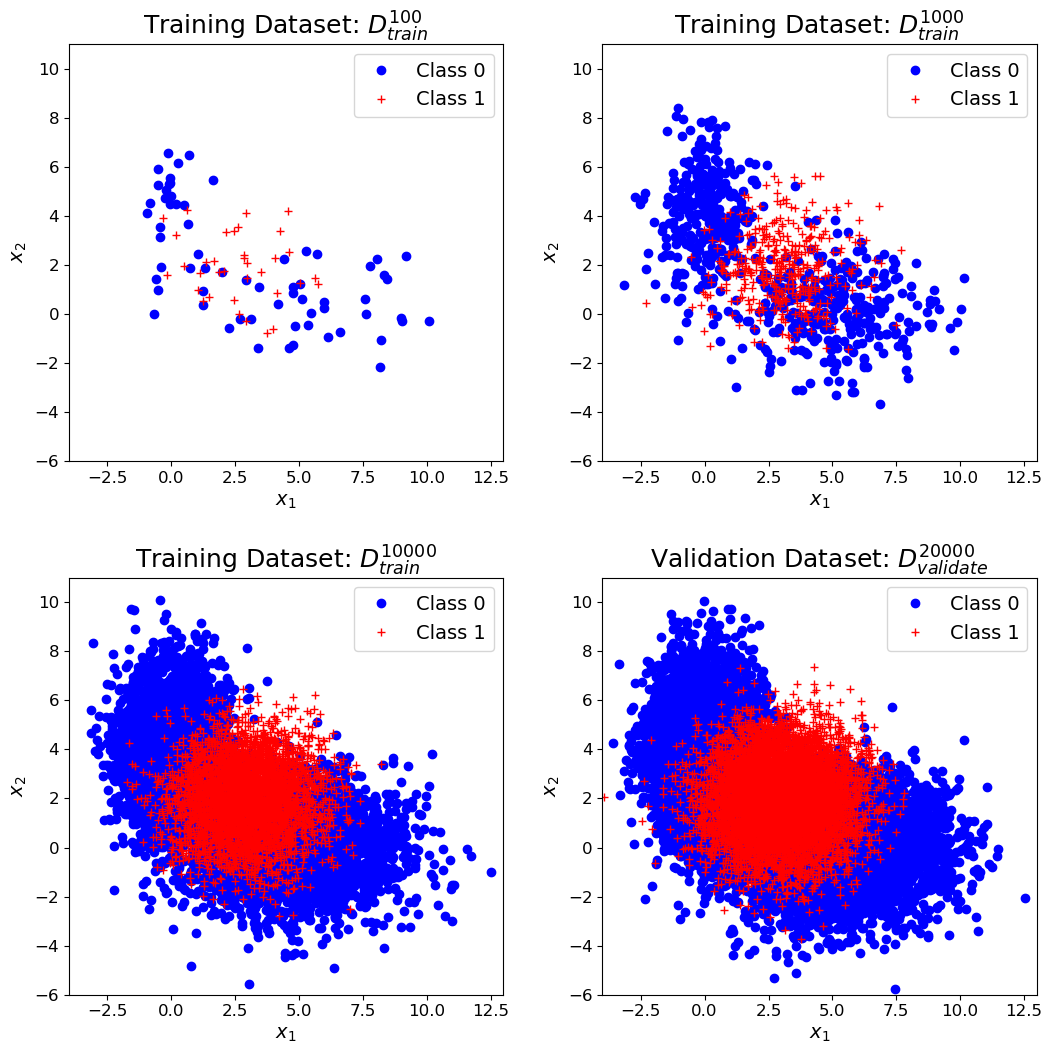

The theoretically optimal classifier that will achieve min-P(error) using the knowledge of true pdf is the ERM classifier with 0-1 loss or Maximum a Posterior (MAP) classifier


$$\frac{p(\mathbf{x}|L=1)}{p(\mathbf{x}|L=0)} > \frac{(\lambda_{10} - \lambda_{00})}{(\lambda_{01} - \lambda_{11})} \frac{P(L=0)}{P(L=1)} 
$$


Since we are assuming 0-1 loss, this decision rule reduces to a MAP classification rule involving the likelihood ratio test of the class-conditional PDFs and the class priors of the model:


$$\ln \frac{p(\mathbf{x}|L=1)}{p(\mathbf{x}|L=0)} > \ln \frac{P(L=0)}{P(L=1)} $$



$$\ln p(\mathbf{x}|L=1) - \ln p(\mathbf{x}|L=0) > \ln \left(\frac{0.6}{0.4}\right)$$



$$\ln p(\mathbf{x}|L=1) - \ln p(\mathbf{x}|L=0) > \ln (1.5)  $$


Thus, the decision rule for the theoretically optimal classifier, are the MAP decision rules: 


$$$\ln p(\mathbf{x}|L=1) - \ln p(\mathbf{x}|L=0) > \ln (1.5) \rightarrow$ Decide Class 1 $(D=1)$$$


and


$$$\ln p(\mathbf{x}|L=1) - \ln p(\mathbf{x}|L=0) < \ln (1.5) \rightarrow$ Decide Class 0 $(D=0)$$$


From here, we will express the decision-threshold value as $\gamma = 1.5$

After evaluating the above decision rule on the $D^{20K}_{validation}$ dataset in Python, the following ROC curve with estimated Empirical and Theoretical min-P(error) were generated as: 

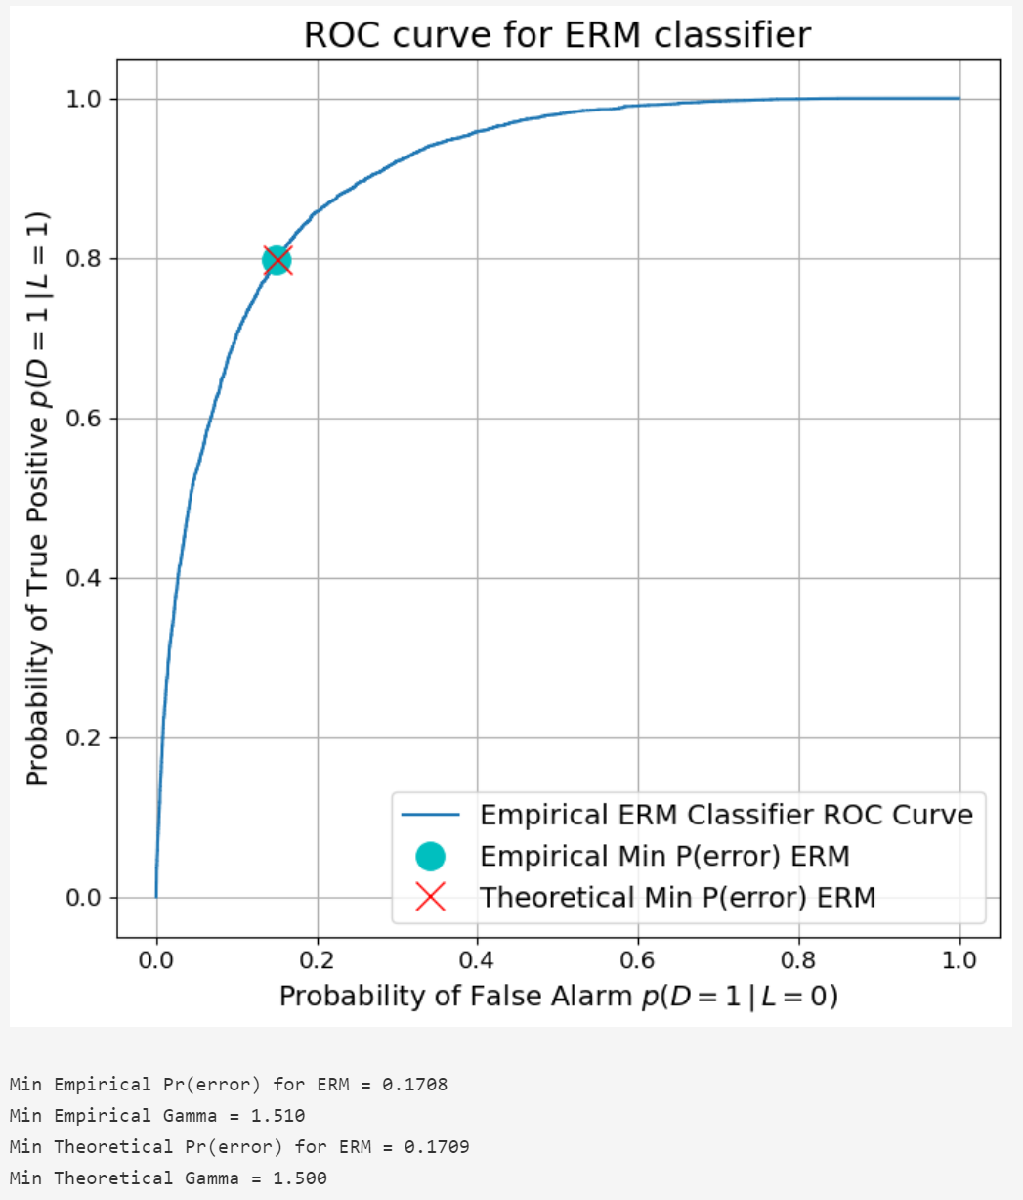

From my estimations:

The minimum empirical $P(error) = 0.1708$ for the ERM Classifier with an empirical value of $\gamma = 1.510$ 

The minimum theoretical $P(error) = 0.1709$ for the ERM Classifier with a theoretical value of $\gamma = 1.5$, which is what was previously calculated above. 

### Part 2: (20%) 

**(a) **Using the maximum likelihood parameter estimation technique, estimate the class priors and class conditional pdfs using training data in $D^{10K}_{train}$. As class conditional pdf models, for $L = 0$ use a Gaussian Mixture model with 2 components, and for $L = 1$ use a single Gaussian pdf model. For each estimated parameter, specify the maximum-likelihood-estimation objective function that is maximized as well as the iterative numerical optimization procedure used, or if applicable, for analytically tractable parameter estimates, specify the estimator formula. Using these estimated class priors and pdfs, design and implement an approximation of the min-P(error) classifier, apply it on the validation dataset $D^{20K}_{validate}$. Report the ROC curve and minimum probability of error achieved on the validation dataset with this classifier that is trained with 10000 samples. 

#### MLE parameters:

For Class 1, since this only a single Gaussian pdf model, the maximum-likelihood-estimations for its parameters can be derived using the Sample Mean, Sample Covariance, and number of training samples to calculate the class prior value. 

The formulas for each would be: 

Sample Mean: 


$$\hat{\mu_k } =\frac{1}{N}\sum_{i=1}^n x_i$$
 

Sample Covariance: 


$$\hat{\Sigma}_k = \sum_{i=1}^{n} (\textbf{x}-\hat{\mu}_k)(\textbf{x}-\hat{\mu}_k)^T$$


Prior: 


$$\pi_k = \frac{N}{n}$$


where the $N$ is the number of training sampled for class 1, and $n$ is the total number of samples in entire dataset $D \in \{100, 1000, 10000\}$

For Class 0, because we are considering it to be a Gaussian Mixture Model with 2 components, we have to use a more complex method for calculating the MLE parameters. 

This can be achieved by using the EM algorithm, where we iteratively compute the most maximum-likelihood for what each parameter for the 2 component GMM should be. This can be down using the following formulas:

In the general case, the MLE for GMM with unknown parameters $\theta = \{\mu_1,\dots,\mu_k,\sigma_1,\dots,\sigma_k,\pi_k,\dots,\pi_k\}$ can be expressed using the likelihood function: 


$$L(\theta|X_i,\dots,X_n) = \prod_{i=1}^{n}\sum_{k=1}^{K}\pi_kN(x_i;\mu_k;\Sigma_k)$$


which can also be expressed in the log-likelihood


$$l(\theta) = \sum_{i=1}^{n}\ln \left(\sum_{k=1}^{K}\pi_kN(x_i;\mu_k;\Sigma_k)\right)$$


where the GMM contains $K$ mixture components.

In order to apply the EM algorithm to a GMM, we first introduce the latent variable $Z_i \in \{1,\dots,K\}$to represent the mixture component for $X_i$, then $P(X_i|Z_i)$ represents the distribution of the mixture component with $\pi_k$ being the mixture prior value for the $k$th component in $X_i$

In the Expectation-Step, we calculate the posterior of $Z_i$:


$$P(Z_i=k|X_i) = \frac{P(X_i|Z_i=k)P(Z_i=k)}{P(X_i)} = \frac{\pi_kN(\mu_k,\Sigma_k)}{\sum_{j=1}^{K}\pi_jN(\mu_j,\Sigma_j)} = \gamma(z_{nk})$$


Then, using the expression for $\gamma(z_{nk})$ into the the formula for EM algorithm:


$$Q(\theta^*|\theta) = E\left[\ln p(\textbf{X},\textbf{Z}|\theta^*)\right] = \sum_{\textbf{Z}}p(\textbf{Z}|\textbf{X},\theta)\ln p(\textbf{X},\textbf{Z}|\theta)$$


where $p(\textbf{Z}|\textbf{X},\theta) = \gamma(z_{nk})$ and $p(\textbf{X},\textbf{Z}|\theta) = \prod_{n=1}^{N}\prod_{k=1}^{K}\pi^{z_{nk}}N(x_n|\mu_k,\Sigma_k)^{z_{nk}}$

The formula for the Expectation-step for the EM algorithm simplifies to:


$$Q(\theta^*|\theta) = \prod_{n=1}^{N}\prod_{k=1}^{K}\gamma(z_{nk})\left[\ln\pi_k + \ln N(x_n|\mu_k,\Sigma_k)\right]$$


The M-Step is then described by: 


$$\theta^* = \underset{\theta} {\mathrm{argmax}}Q(\theta^*|\theta)$$


where the old values of $\theta$ are used to calcualte the new values $\rightarrow \theta^*$

The MLE parameters are then estimated for the GMM by: 

$\pi_k = \frac{\sum_{n=1}^{N}\gamma(z_{nk})}{N}$;     $\mu_k^* = \frac{\sum_{n=1}^{N}\gamma(z_{nk})\textbf{x}_n}{\sum_{n=1}^{N}\gamma(z_{nk})}$;     $\Sigma_k^* = \frac{\sum_{n=1}^{N}\gamma(z_{nk})(\textbf{x}_n-\mu_k)(\textbf{x}_n-\mu_k)^T}{\sum_{n=1}^{N}\gamma(z_{nk})}$

We then use the newly estimated values for the parameters to then calculate $\gamma$ in the following E-Step and repeat the process until the parameters converge to a particular set of values. 

The estimated values from the $D^{10K}_{train}$ dataset using the **estimateMLE()** function in the Appendix, yielded:

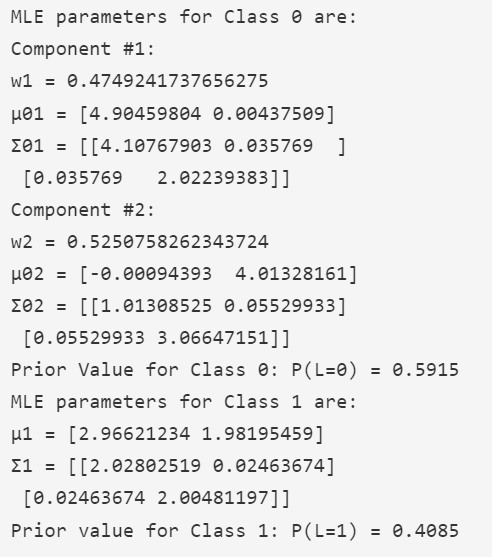

Using these estimated parameters from the $D^{10K}_{train}$ dataset, I generated the priors and class-conditional pdfs for Class 0 and Class 1, and approximated the min-$P(error)$ classifier and applied it the the $D^{20K}_{validate}$ dataset to achieve the following ROC curve and min-$P(error)$: 

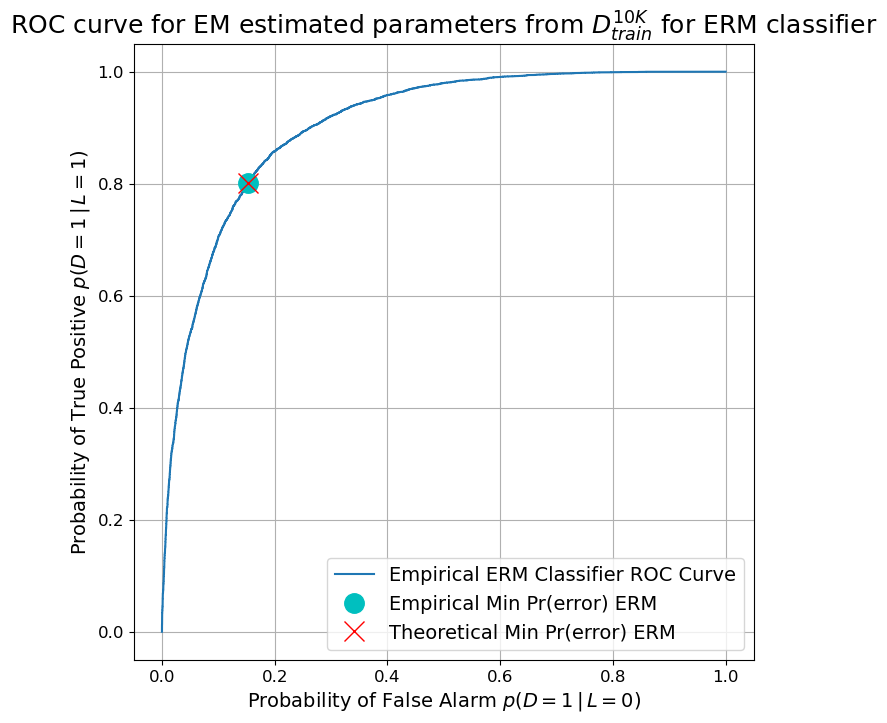

This approximation of the ERM classifer achieved an empirical min-$P(error)$$=0\ldotp 1708$

**(b)** Repeat Part (2a) using $D^{1000}_{train}$ as the training dataset. 

The estimated values from the $D^{1000}_{train}$ dataset using the **estimateMLE()** function in the Appendix, yielded:

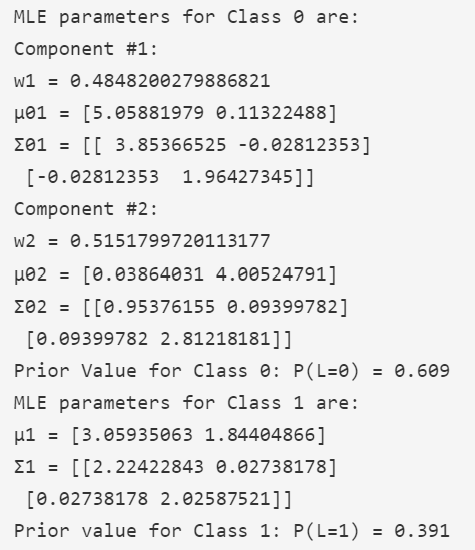

Using these estimated parameters from the $D^{1000}_{train}$ dataset, I generated the priors and class-conditional pdfs for Class 0 and Class 1, and approximated the min-$P(error)$ classifier and applied it the the $D^{20K}_{validate}$ dataset to achieve the following ROC curve and min-$P(error)$:

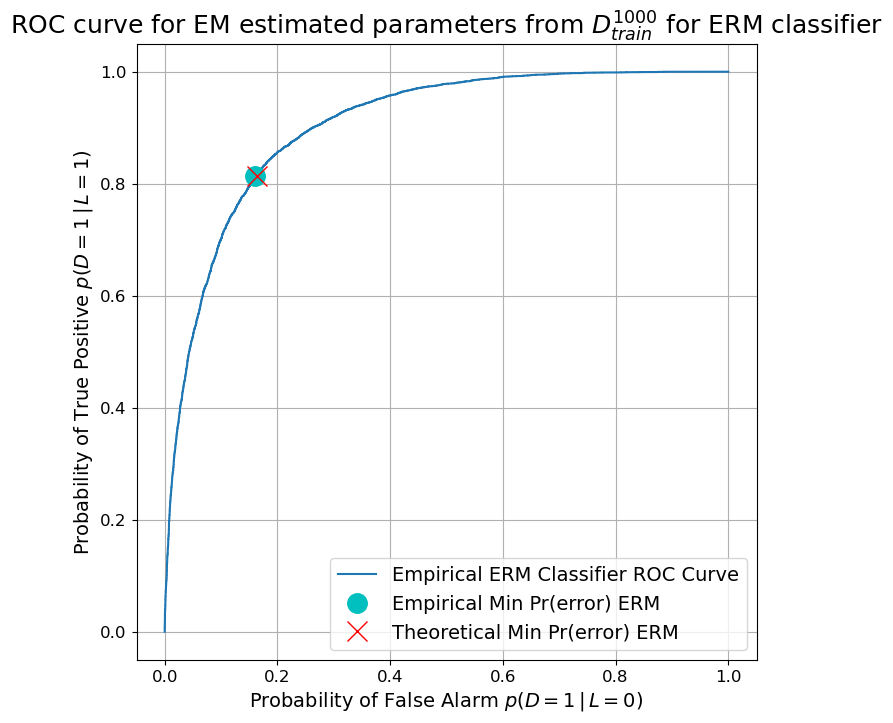

This approximation of the ERM classifer achieved an empirical min-$P(error)$$=0\ldotp 1713$

**(c)** Repeat Part (2a) using $D^{100}_{train}$ as the training dataset. How does the performance of your approximate min-P(error) classifier change as the model parameters are estimated (trained) using fewer samples?

The estimated values from the $D^{100}_{train}$ dataset using the **estimateMLE()** function in the Appendix, yielded:

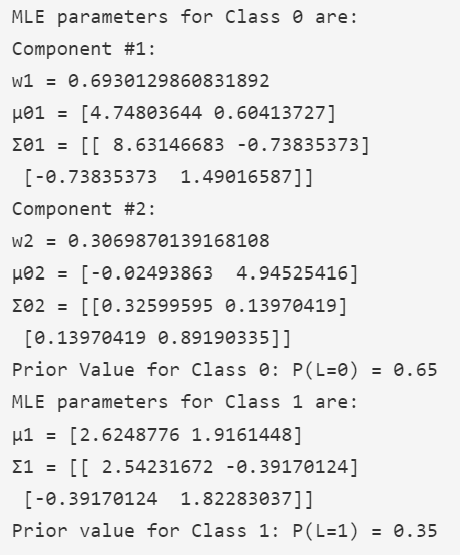

Using these estimated parameters from the $D^{100}_{train}$ dataset, I generated the priors and class-conditional pdfs for Class 0 and Class 1, and approximated the min-$P(error)$ classifier and applied it the the $D^{20K}_{validate}$ dataset to achieve the following ROC curve and min-$P(error)$:

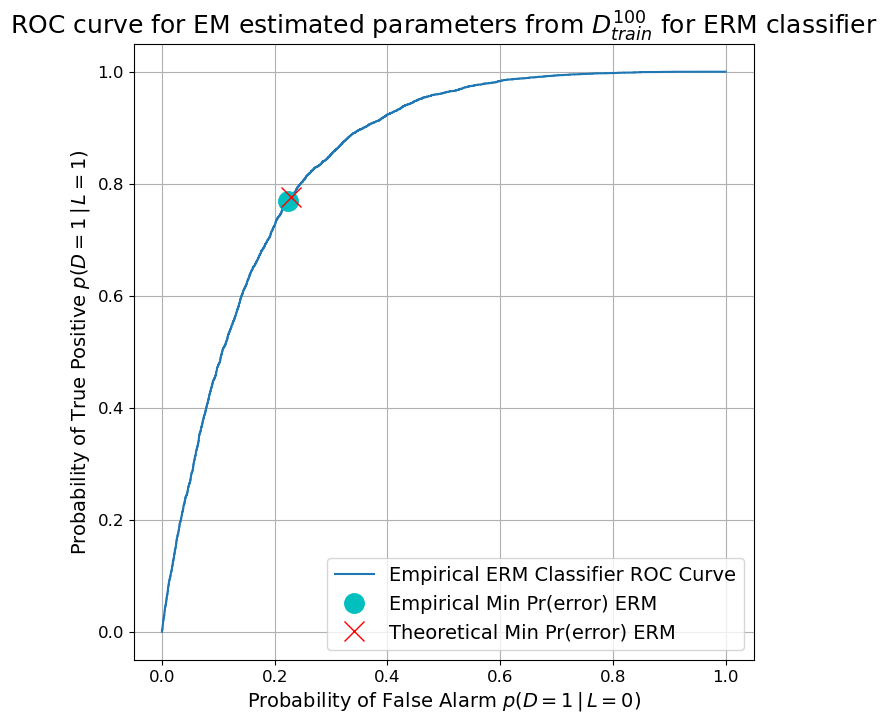

This approximation of the ERM classifer achieved an empirical min-$P(error)$$=0\ldotp 2260$

From the repeated estimations of the ROC curves using the training sets, we can observe that the performance of the min-$P(error)$ classifier is dependent on the number of training samples we used before attempting to classifiy the $D^{20K}_{validate}$ dataset. We observe that the performance of the min-$P(error)$ classifier and ROC curves becomes worse when using less and less training samples.  

When using the $D^{10K}_{train}$ dataset, the ROC curve looks almost identical to the ROC curve generated from the $D^{20K}_{validate}$ dataset and generated an empirical min-$P(error)$ = 0.1708, which was identical in value to the min-$P(error)$ achieved with the $D^{10K}_{train}$ dataset  

When using the $D^{1000}_{train}$ dataset, the ROC curve has looks worse than the previous and generated an empirical min-$P(error)$ = 0.1713, which is not that much of a increase in performance error 

Lastly, when using the $D^{100}_{train}$ dataset, the ROC curve has a less arch to its shape signifiying a weaker performance for this iteration of the ERM classifier. This is also evidence from the achieved empirical min-$P(error)$ = 0.2260.    

This demonstrates that when we are data-starved for training samples for our ERM classifier we should expect a poorer performance than if we have an abundance of training samples.

### Part 3: (20%) 

**(a)** Using the maximum likelihood parameter estimation technique train a logistic-linear-function-based approximation of class label posterior function given a sample. As in part 2, repeat the training process for each of the three training sets to see the effect of training set sample count; use the validation set for performance assessment in each case. When optimizing the parameters, specify the optimization problem as minimization of the negative-log-likelihood of the training dataset, and use your favorite numerical optimization approach, such as gradient descent or Matlab’s *fminsearch* or Python’s *minimize*. Use the trained class-label-posterior approximations to classify validation samples to approximate the minimum-P(error) classification rule; estimate the probability of error that these three classifiers attain using counts of decisions on the validation set.

**Optional**: As supplementary visualization, generate plots of the decision boundaries of these trained classifiers superimposed on their respective training datasets and the validation dataset. 

Our binary logistic regression model of class label posterior function can be specified as


$$p(l|\mathbf{x}; \textbf{\theta}) = g\left(\mathbf{w}^T \phi(\mathbf{x})\right)^l \left(1-g(\mathbf{w}^T\phi(\mathbf{x}))\right)^{(1-l)}$$


where $g(z)$ represents the sigmoid function, $l$ is the true class label (0 or 1), and $\phi(x)$ is a new feature matrix consisting of all polynomial combinations of the features $\textbf{x}$ (this definition applies to both the linear case $\phi(\textbf{x}) =$ degree 1 and quadratic case  $\phi(\textbf{x}) =$ degree 2) 

We wish to express this class label posterior function in terms of its Log-Likelihood form given $N$ samples in the dataset: 


$$LL(\theta) = \frac{1}{N} \sum_{i=1}^{N}\Big[l^{(i)} \log g\Big(\textbf{w}^{T}\phi(\textbf{x}^{(i)})\Big) + (1-l^{(i)})\log\Big(1-g(\textbf{w}^{T}\phi(\textbf{x}^{(i)}))\Big)\Big]$$


In order to derive the MLE for the model's parameters, $\theta$, by minimizing the Negative-Log-Likelihood in order to derive $\theta_{MLE} = \textbf{w}^*$

This expression is of the form


$$\mathbf{w}^* = \underset{\theta} {\mathrm{argmin}}\text{NLL}(\textbf{\theta}) = - \frac{1}{N} \sum_{i=1}^N \Big[ {l^{(i)}} \log g\big(\mathbf{w}^T\phi(\mathbf{x}^{(i)})\big) + (1-l^{(i)}) \log \big(1-g(\mathbf{w}^T \phi(\mathbf{x}^{(i)}))\big) \Big]$$


Then after obtaining our MLE parameter of $\textbf{w}^*$, we derive our min-$P(error)$ decision rule using the sigmoid function's shape for our predictions, and generate the following decision rule: 


$$g\left(\mathbf{w}^{*T} \phi(\mathbf{x}^{(i)})\right) \geq 0.5 \rightarrow \text{Decide Class 1} \rightarrow(D=1)
$$



$$g\left(\mathbf{w}^{*T} \phi(\mathbf{x}^{(i)})\right) < 0.5 \rightarrow \text{Decide Class 0} \rightarrow(D=0)
$$


These decisions reflect the situation where if comparing the posteriors, our decision is made from whichever class posterior is greater, 

e.g. we choose Class 1 if $p(L=1|x;\theta) > p(L=0|x;\theta)$, else we would choose Class 0. 

This corresponds to the inner argument of the sigmoid function specifying the decision rule by:


$$\mathbf{w}^{*T} \phi(\mathbf{x}^{(i)})\geq 0 \rightarrow \text{Decide Class 1} \rightarrow(D=1)
$$



$$\mathbf{w}^{*T} \phi(\mathbf{x}^{(i)}) < 0 \rightarrow \text{Decide Class 0} \rightarrow(D=0)
$$


Using the Python code in Appendix: Question 1 Part 3(a), I was able to generate the following plots and their corresponding approximations of the min-$P(error)$ classifiers using a logistic-linear-function-based approximation of class label posteriors

Starting with the Logistic-Linear Model trained using the $D^{10K}_{train}$ dataset:

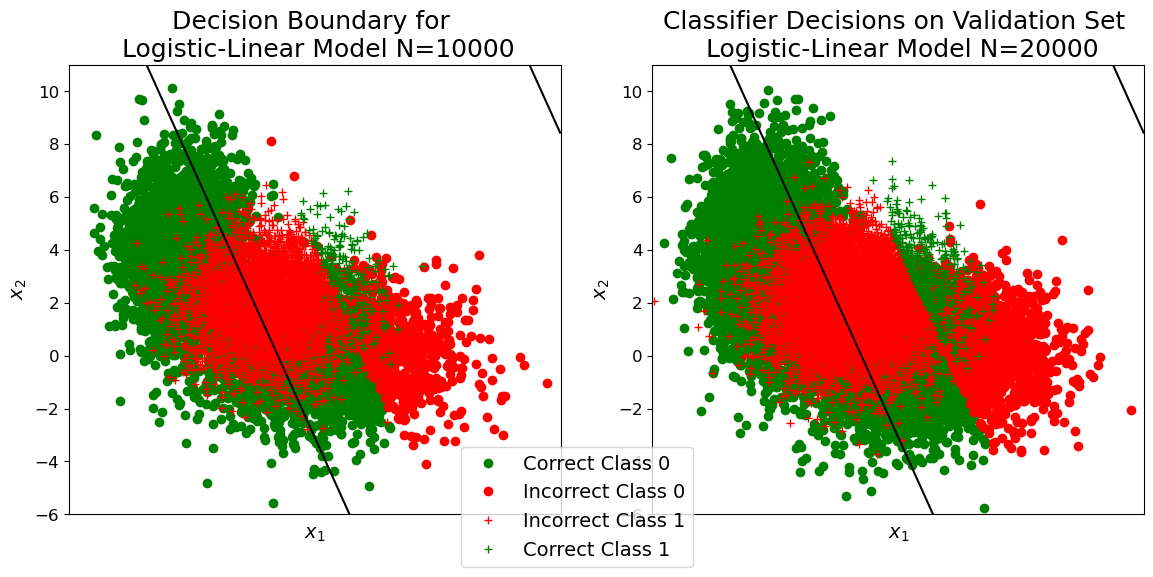

I estimated the MLE parameter $\textbf{w}^* = [-0.842, 0.1353, 0.0558]^T$ with a min-$P(error) = 0.461$ 

The linear decision boundaries were derived from the $\phi$-transformation of input features $\textbf{x}$ and superimposed on the training and validation datasets

Next, the Logistic-Linear Model trained using the $D^{1000}_{train}$ dataset:

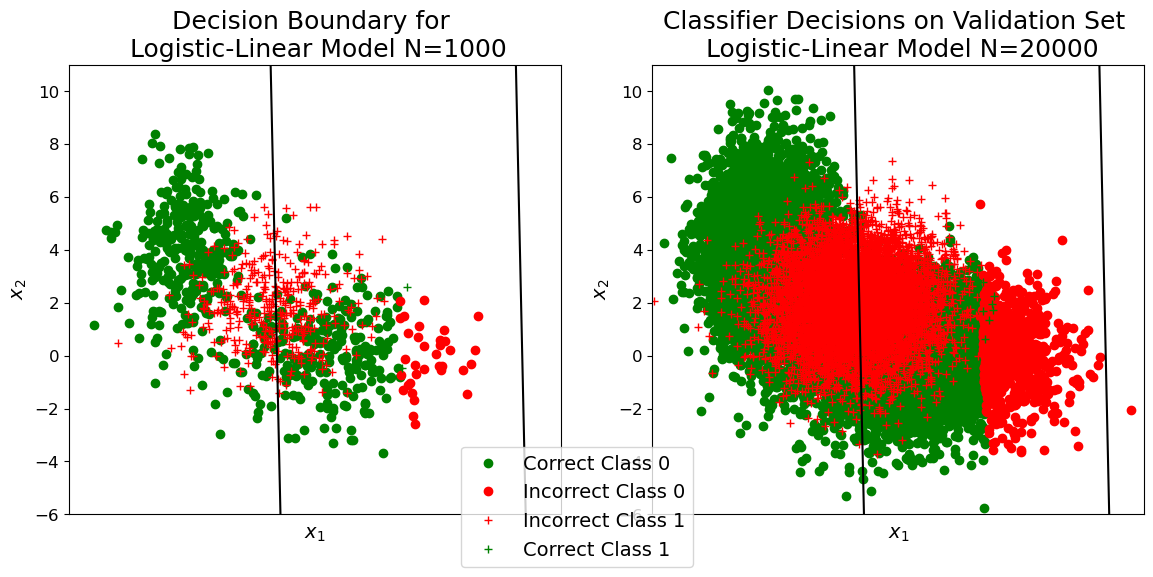

I estimated the MLE parameter $\textbf{w}^* = [-0.7111, 0.0956, 0.0019]^T$ with a min-$P(error) = 0.435$ 

Again, decision boundaries were derived from the $\phi$-transformation of input features $\textbf{x}$ and superimposed on the training and validation datasets

Lastly, the Logistic-Linear Model trained using the $D^{100}_{train}$ dataset:

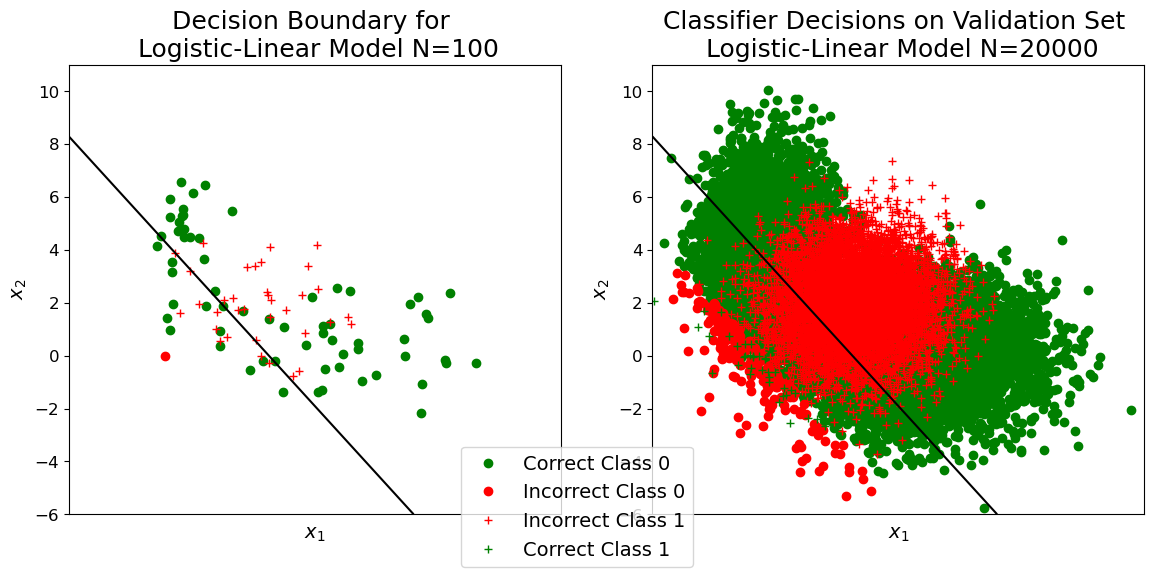

I estimated the MLE parameter $\textbf{w}^* = [-0.0247, -0.1306, -0.1089]^T$ with a min-$P(error) = 0.412$ 

Again, decision boundaries were derived from the $\phi$-transformation of input features $\textbf{x}$ and superimposed on the training and validation datasets

We observe that the performance of the Logistic-Linear models performed worse as the number of training samples increased and that the decision boundaries generated with less samples generated a better min-$P(error)$ classifier. Though, this seems to have just been circumstantial and no amount of data would generate a better linear decision boundary. 

**(b)** Repeat the process described in Part (3a) using a logistic-quadratic-function-based approximation of class label posterior functions given a sample.

Again, using the Python code in Appendix: Question 1 Part 3(b), I was able to generate the following plots and their corresponding approximations of the min-$P(error)$ classifiers using a logistic-quadratic-function-based approximation of class label posteriors

Starting with the Logistic-Quadratic Model trained using the $D^{10K}_{train}$ dataset:

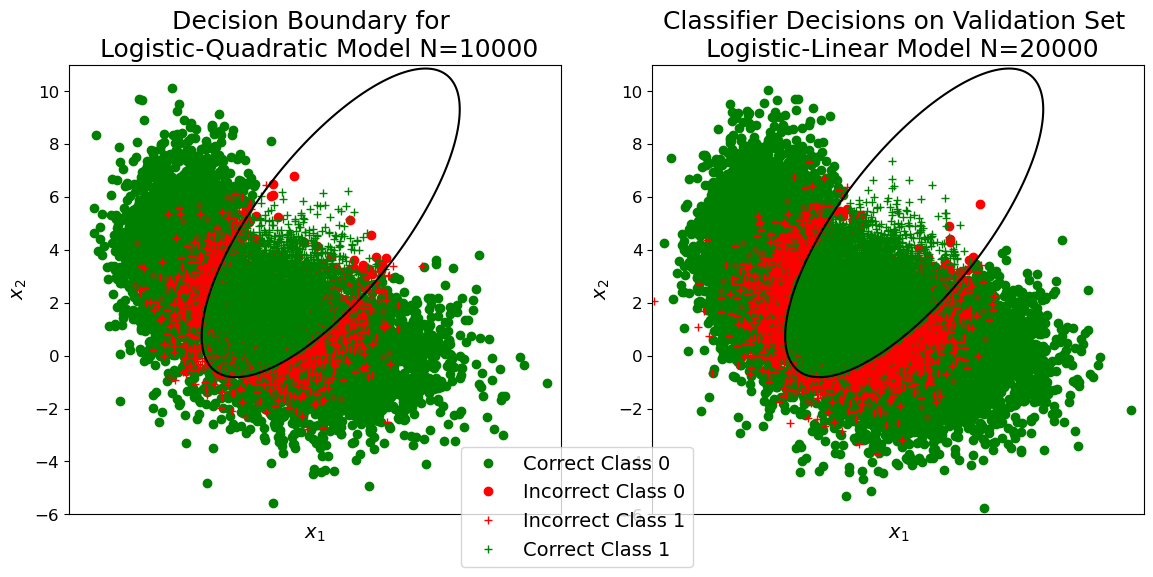

I estimated the MLE parameter $\textbf{w}^* = [-0.7019, 1.2035, 0.0518,-0.2699,0.3035,-0.1578]^T$ with a min-$P(error) = 0.174$ 

The quadratic decision boundaries were derived from the $\phi$-transformation of input features $\textbf{x}$ and superimposed on the training and validation datasets

Next, the Logistic-Quadratic Model trained using the $D^{1000}_{train}$ dataset:

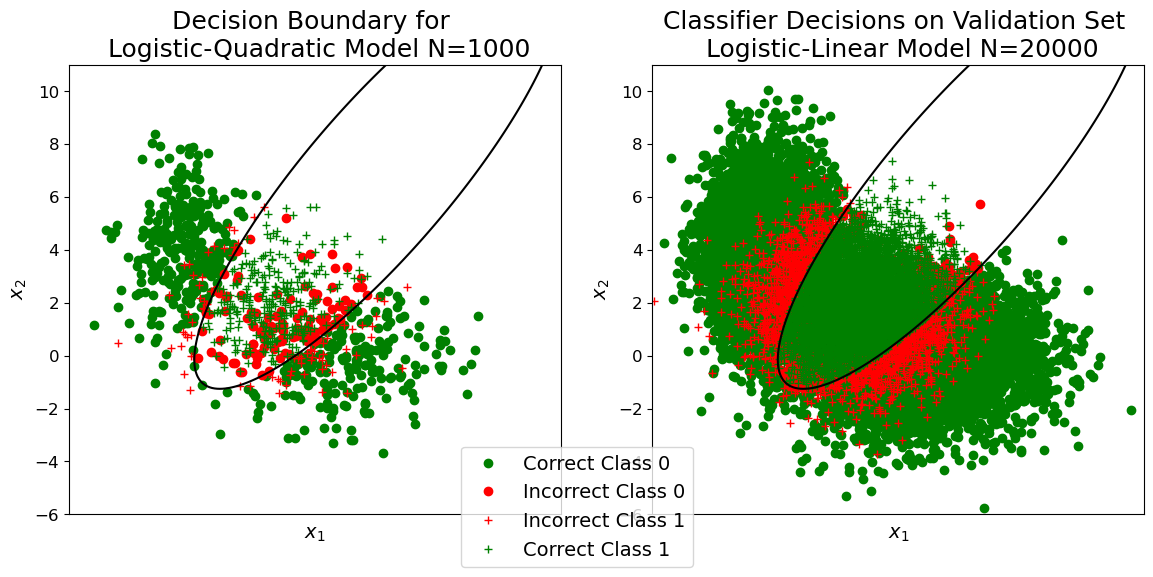

I estimated the MLE parameter $\textbf{w}^* = [-0.3098, 0.9914, -0.1569, -0.2379,  0.3282,  -0.1527]^T$ with a min-$P(error) = 0.176$ 

Again, quadratic decision boundaries were derived from the $\phi$-transformation of input features $\textbf{x}$ and superimposed on the training and validation datasets

Lastly, the Logistic-Quadratic Model trained using the $D^{100}_{train}$ dataset:

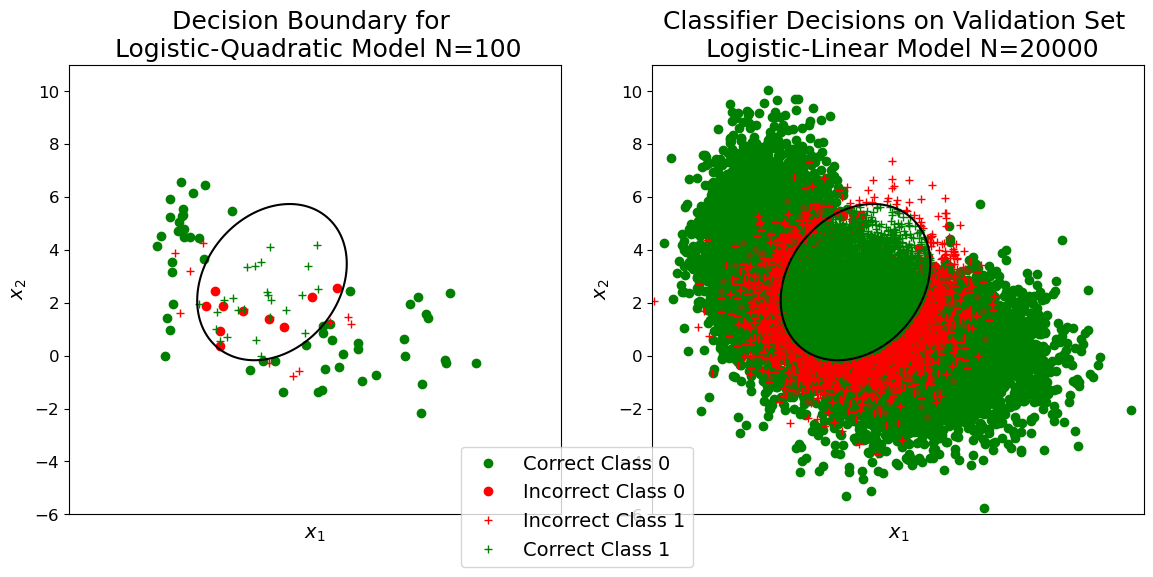

I estimated the MLE parameter $\textbf{w}^* = [-1.4173,   1.3144, 0.80943457 -0.2683,  0.1106,  -0.2056]^T$ with a min-$P(error) = 0.190$ 

Again, quadratic decision boundaries were derived from the $\phi$-transformation of input features $\textbf{x}$ and superimposed on the training and validation datasets

The keytakeaway for the Logistic-Quadratic model is that the min-$P(error)$ classifier performed between when the number of training samples increased and was superior to the logistic-linear model. Again, these decision boundaries were circumstantially-derived based on the random placement of training samples. Though, provided with more training samples, the logistic-quadratic model was able to draw decision boundaries that resulted in a fairly accurate classifer, but was still did not outperform the theoretically optimal model of Part 1. 

## Question 2 (30%)

A vehicle at true position $[x_T , y_T ]^T$ in 2-dimensional space is to be localized using distance (range) measurements to $K$ reference (landmark) coordinates $\{[x_1, y_1]^T,\dots,[x_i, y_i]^T,\dots,[x_K, y_K]^T\}$. These range measurements are $r_i = d_{Ti} +n_i$ for $i \in \{1,\dots,K\},$ where $d_{Ti} = \Vert[x_T , y_T ]^T - [x_i,y_i]^T\Vert$ is the true distance between the vehicle and the $i^{th}$ reference point, and $n_i$ is a zero mean Gaussian distributed measurement noise with known variance $\sigma^2_i$. The noise in each measurement is independent from the others. Assume that we have the following prior knowledge regarding the position of the vehicle:


$$p\left(\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack \right)={\left(2\pi \sigma_x \sigma_y \right)}^{-1} e^{-\frac{1}{2}\left\lbrack \begin{array}{cc}
x & y
\end{array}\right\rbrack {\left\lbrack \begin{array}{cc}
\sigma_x^2  & 0\\
0 & \sigma_y^2 
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack }$$


where $[x,y]^T$ indicates a candidate position under consideration

**Expression the optimization problem **that needs to be solved to determine the MAP estimate of the vehicle position. Simplify the objective function so that the exponentials and additive/multiplicative terms that do not impact the determination of the MAP estimate $[x_{MAP}, y_{MAP}]^T$ are removed appropriately from the objective function for computational savings when evaluating the objective.

We can express the optimization problem by solving for the values that maximize the Posterior objective function: 


$$p([x_T,y_T]^T|r_i) = \prod_{i=1}^Kp(r_i|[x_T,y_T]^T)$$

$$P\left(\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack \right)$$


The Posterior of the objective function is expressed as the likelihood that some noisy distance measurement is the true position of the vehicle, multiplied by the prior knowledge of the vehicle. And since each distance measurement is independent, we can express $K$ distance measurements as the product of the per-base-station likelihoods. 

Elaborating further, we can take the log-posterior which would simplify the right-hand side into the sum of the log-likelihoods added together with the log of the prior knowledge


$$\ln p([x_T,y_T]^T|r_i) = \sum_{i=1}^K \ln p(r_i|[x_T,y_T]^T)$$

$$+\;\ln \;P\left(\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack \right)$$


Simplifying the log of the prior knowledge: 


$$\ln p([x_T,y_T]^T|r_i) = \sum_{i=1}^K  \sqrt{(x_i-x_T)^2+(y_i-y_T)^2} + n_i $$

$$+\;\ln \;\left({\left(2\pi \sigma_x \sigma_y \right)}^{-1} \right)-\frac{1}{2}\left\lbrack \begin{array}{cc}
x & y
\end{array}\right\rbrack {\left\lbrack \begin{array}{cc}
\sigma_x^2  & 0\\
0 & \sigma_y^2 
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack$$



$$\ln p([x_T,y_T]^T|r_i) = \sum_{i=1}^K  \sqrt{(x_i-x_T)^2+(y_i-y_T)^2} + n_i $$

$$-\;\ln \;\left(2\pi \sigma_x \sigma_y \right)-\frac{1}{2}\left(\frac{x^2 }{\sigma_x^2 }+\frac{y^2 }{\sigma_y^2 }\right)$$



$$LL = - \sum_{i=1}^K \sqrt{(x_i-x_T)^2+(y_i-y_T)^2} + n_i + \ln(2\pi\sigma_x\sigma_y) + (1/2)\left(\frac{x^2}{\sigma_x^2} + \frac{y^2}{\sigma_y^2}\right)$$


Simplifying and removing the constant terms, we have the Log-Likelihoods is: 


$$LL = - \sum_{i=1}^Kr_i + \ln(2\pi\sigma_x\sigma_y) + (1/2)\left(\frac{x^2}{\sigma_x^2} + \frac{y^2}{\sigma_y^2}\right)$$


**Implement the following as computer code: ** Set the true vehicle location to be inside the circle with unit radius centered at the origin. For each $K \in \{1,2,3,4\}$ repeat the following. 

- Place evenly spaced $K$ landmarks on a circle with unit radius centered at the origin. 

- Set measurement noise standard deviation to 0.3 for all range measurements. 

- Generate $K$ range measurements according to the model specified above (if a range measurement turns out to be negative, reject it and resample; all range measurements need to be nonnegative).

- Plot the equilevel contours of the MAP estimation objective for the range of horizontal and vertical coordinates from -2 to 2; superimpose the true location of the vehicle on these equilevel contours (e.g. use a + mark), as well as the landmark locations (e.g. use a $o$ mark for each one).

- Provide plots of the MAP objective function contours for each value of $K$. When preparing your final contour plots for different $K$ values, make sure to plot contours at the same function value across each of the different contour plots for easy visual comparison of the MAP objective landscapes. $Suggestion$: For values of $\sigma_x$ and $\sigma_y$, you could use values around 0.25 and perhaps make them equal to each other. Note that your choice of these indicates how confident the prior is about the origin as the location.

- Supplement your plots with a brief description of how your code works. Comment on the behavior of the MAP estimate of position (visually assessed from the contour plots; roughly center of the innermost contour) relative to the true position. Does the MAP estimate get closer to the true position as $K$ increases? Does is get more certain? Explain how your contours justify your conclusions.

% Parameters for PDF of Vehicle Position
mu = [0 0]; sig_x = 0.25; sig_y = 0.25; sig_n = 0.3;
Sigma = [sig_x^2 0; 0 sig_y^2];
% Create Meshgrid for contour plots
xT = -2:.01:2; yT = -2:.01:2;
[XT,YT] = meshgrid(xT,yT);
XY = [XT(:) YT(:)];
% Generate PDF for prior knowledge of vehicle position 


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


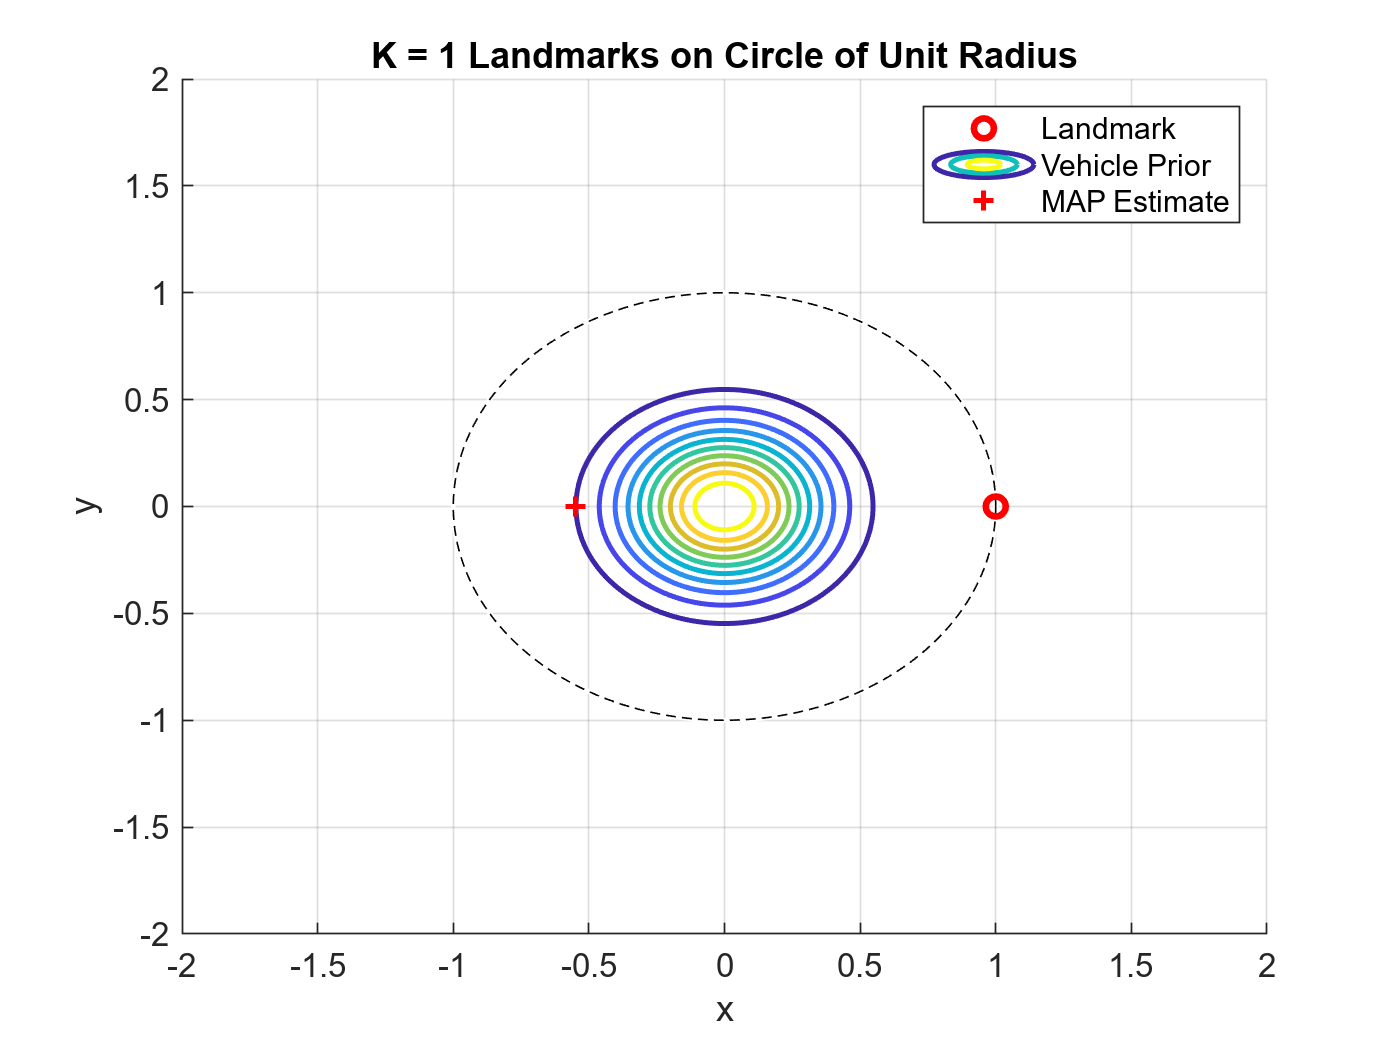

P = mvnpdf(XY,mu,Sigma);
P = reshape(P,length(yT),length(xT));
K = 1;
lb = [-0.5475 -0.5475];

ub = [0.5475 0.5475];
x0 = [0 0]; 
obj = @(x)LogLikelihood(K,x);
P1 = fmincon(obj,x0,[],[],[],[],lb,ub);
figure(1)
[Kx1,Ky1] = Q2plotKContours(K,xT,yT,P);
plot(P1(1),P1(2),'r+','LineWidth',1.5), hold off, pause(1)
legend('Landmark','Vehicle Prior','MAP Estimate')


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


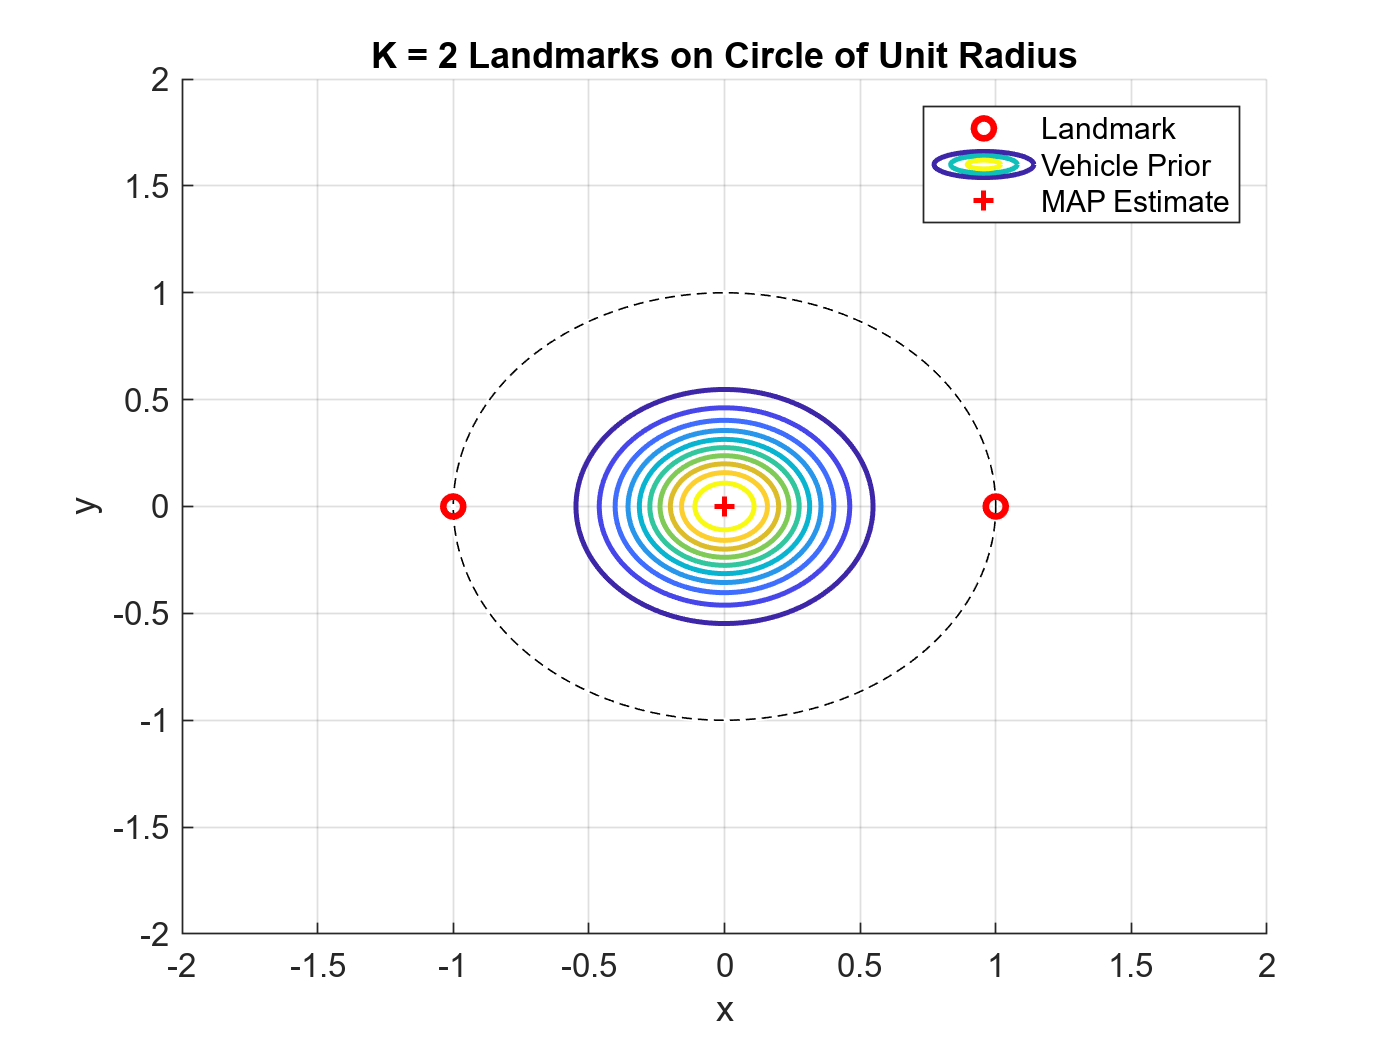

K = 2;
figure(2)

[Kx2,Ky2] = Q2plotKContours(K,xT,yT,P);
lb = [-0.5475 -0.5475];
ub = [0.5475 0.5475];
x0 = [0 0]; 
obj = @(x)LogLikelihood(K,x);
xopt = fmincon(obj,x0,[],[],[],[],lb,ub);
plot(xopt(1),xopt(2),'r+','LineWidth',1.5), hold off, pause(1)
legend('Landmark','','Vehicle Prior','MAP Estimate')


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


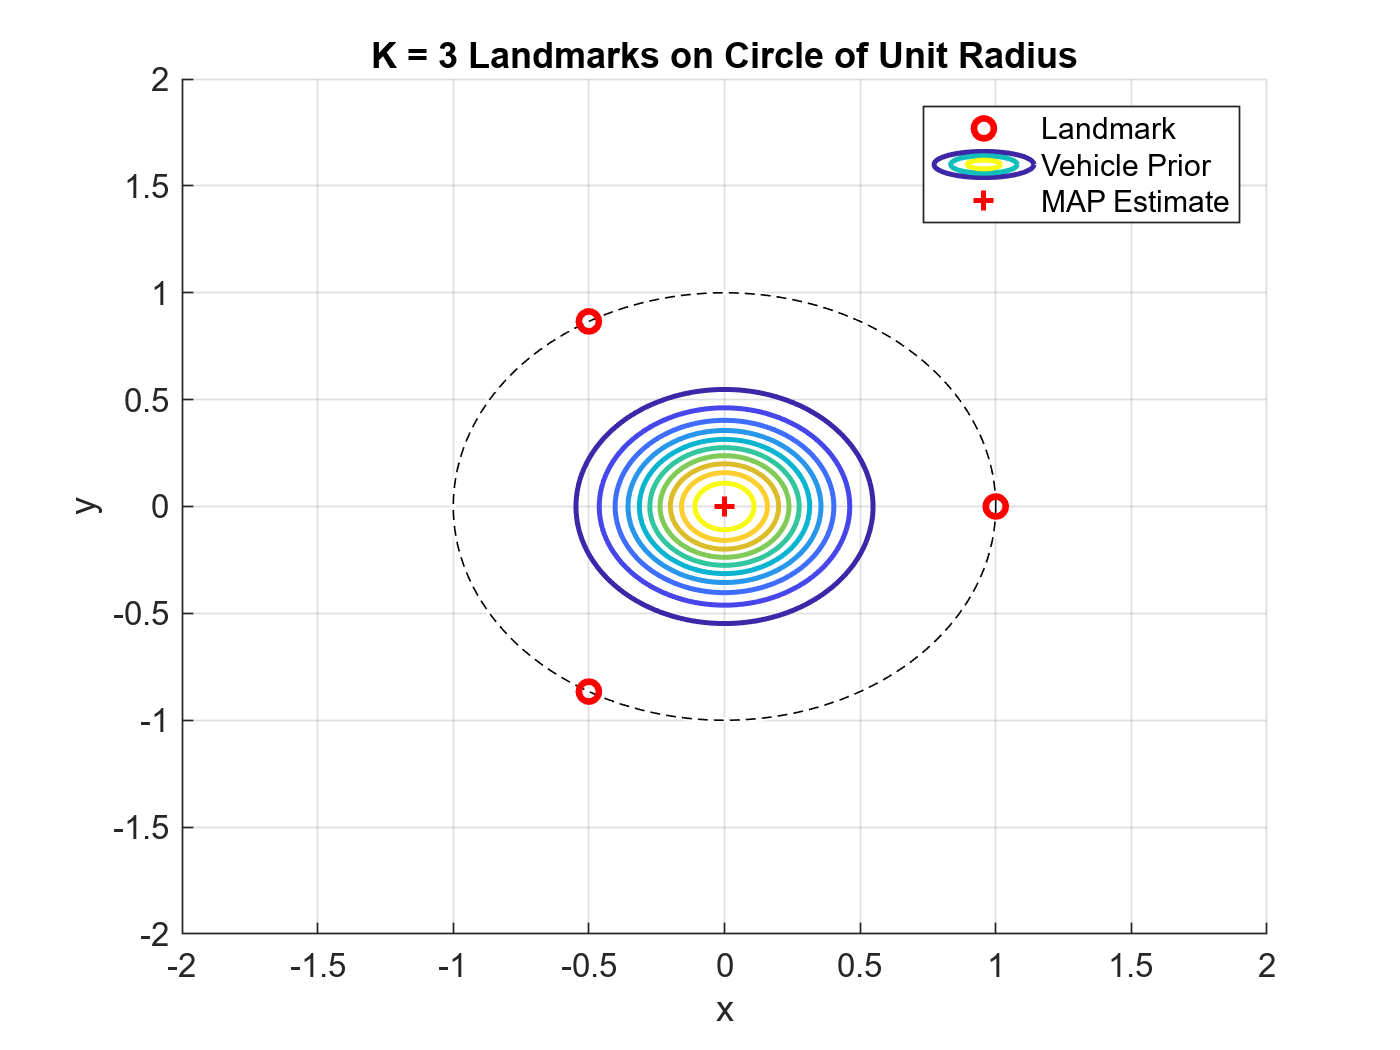

K = 3;
figure(3)

[Kx3,Ky3] = Q2plotKContours(K,xT,yT,P);
lb = [-0.5475 -0.5475];
ub = [0.5475 0.5475];
x0 = [0 0]; 
obj = @(x)LogLikelihood(K,x);
xopt = fmincon(obj,x0,[],[],[],[],lb,ub);
plot(xopt(1),xopt(2),'r+','LineWidth',1.5), hold off, pause(1)
legend('Landmark','','','Vehicle Prior','MAP Estimate')


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


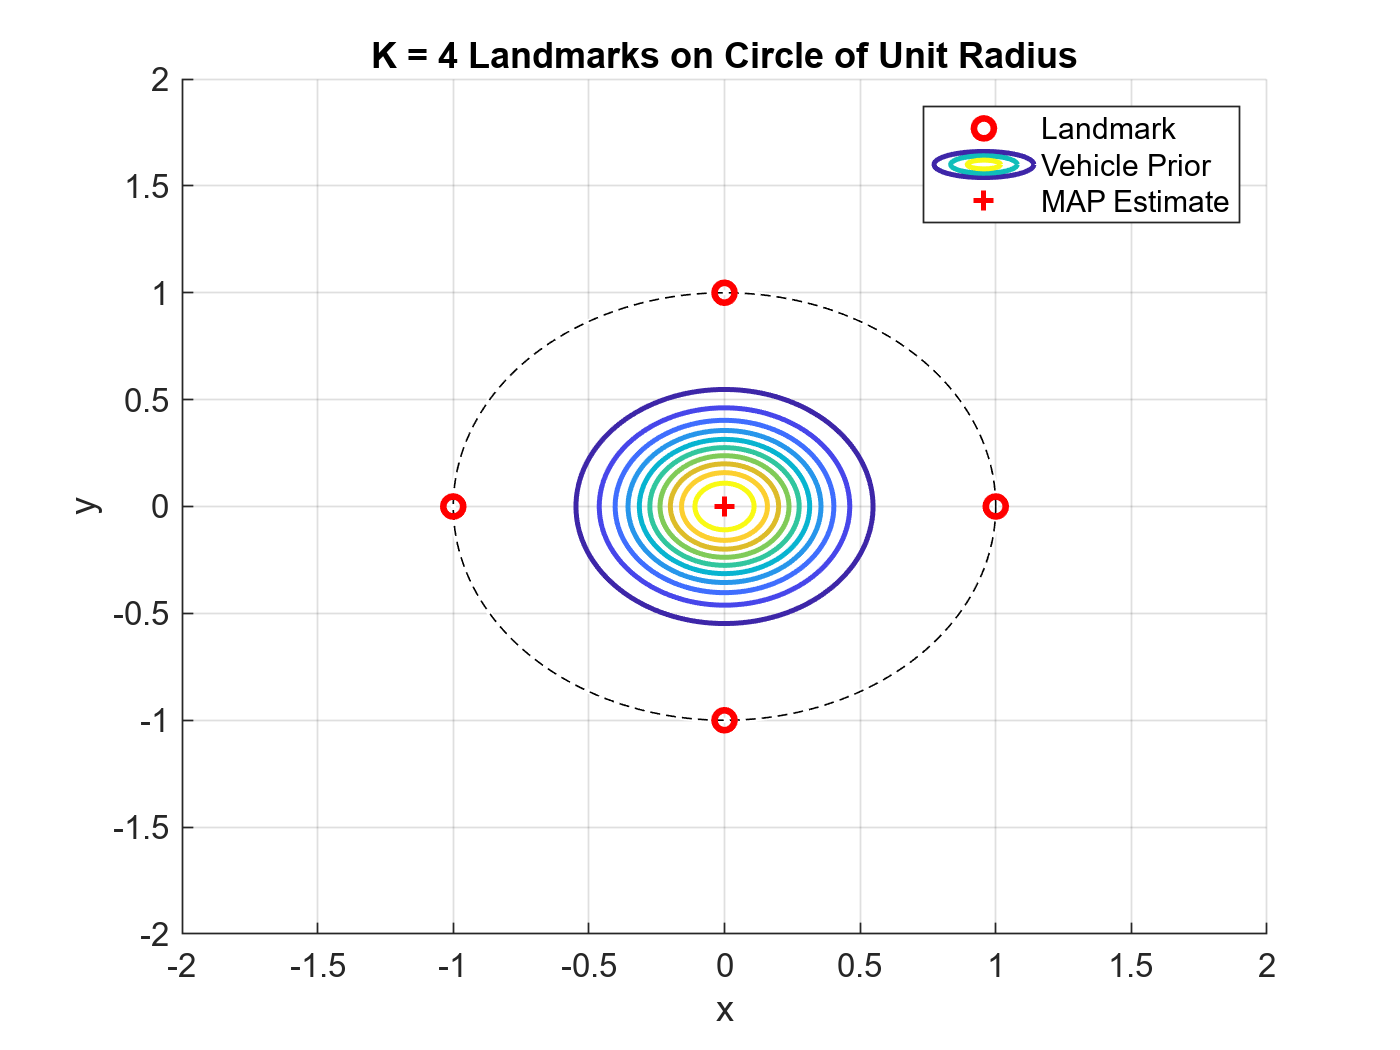

K = 4;
figure(4)

[Kx4,Ky4] = Q2plotKContours(K,xT,yT,P);
lb = [-0.5475 -0.5475];
ub = [0.5475 0.5475];
x0 = [0 0]; 
obj = @(x)LogLikelihood(K,x);
xopt = fmincon(obj,x0,[],[],[],[],lb,ub);
plot(xopt(1),xopt(2),'r+','LineWidth',1.5), hold off, pause(1)
legend('Landmark','','','','Vehicle Prior','MAP Estimate')

From the above plots, we visualize the MAP estimates on the Vehicle Prior contours as the number of landmark references increases from one to four. When there is only one landmark reference, the uncertainty of the vehicle's position is at the highest of each of the plots and guesses the vehicle's location to be along the outer edge of the prior knowledge contour. 

As the number of landmark references increases to two, the uncertainty of the MAP estimate drops and finds the local minimum for the vehicle's position to be centered at the origin. This uncertainty steadily decreases as the number of landmark references increases, but remains nonzero due to the additive noise for each of the $K$ distance measurements. Since the prior knowledge assumes the form of a white Gaussian distribution centered at the origin, the local minimum achieved is at the origin of the prior knowledge which confirms the convergence for the true vehicle position to be at the origin for $K > 1$ landmark references. 

## Question 3 (20%)

Problem 2.13 from Duda-Hart textbook: 

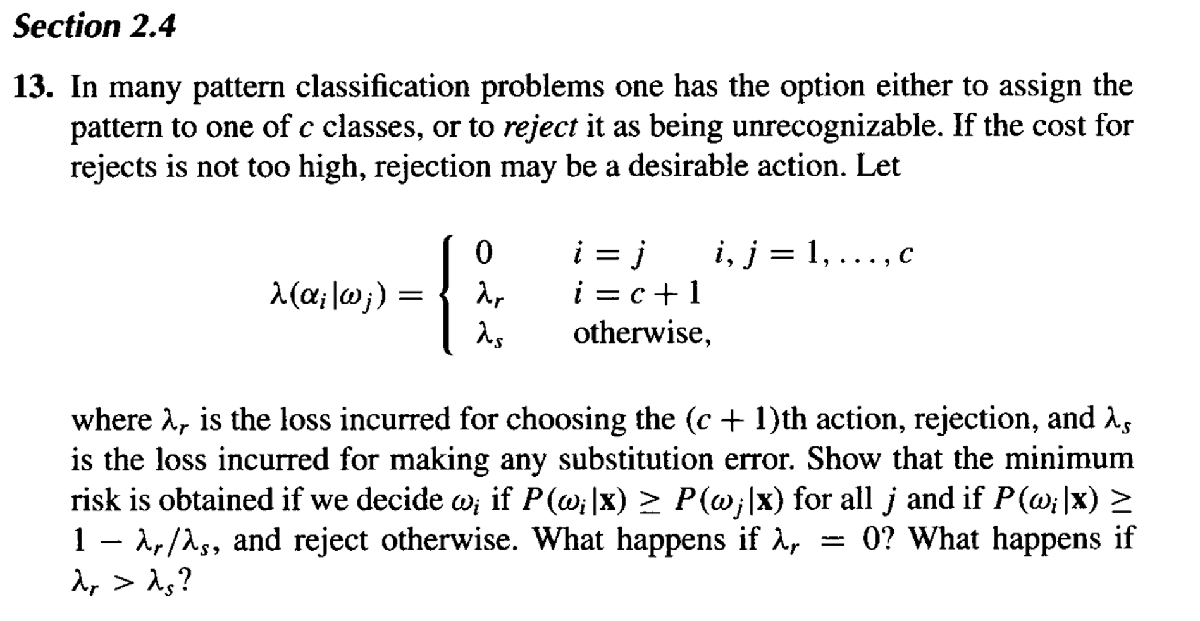

Let's first define the expression for conditional risk for $c$ number of classes: 


$$R(\alpha_i|\textbf{x}) = \sum_{j=1}^{c} \lambda(\alpha_i|\omega_j)P(\omega_j|\textbf{x}) $$


where $i,j=1,\ldots,c$ and $\alpha_i$ is the action we take that minimizes the conditional risk $R(\alpha_i|\textbf{x})$

The conditional risk for the action of rejection can be defined as:


$$R(\alpha_{c+1}|\textbf{x}) = \lambda_r$$


Then including the expected loss term $\lambda_s$ into the expression for conditional risk


$$R(\alpha_i|\textbf{x}) =  \lambda_s\sum_{j=1}^{c} \lambda(\alpha_i|\omega_j)P(\omega_j|\textbf{x}) $$


            
$$= \lambda_s\sum_{j\neq i}^c P(\omega_j|\textbf{x})$$


            
$$= \lambda_s(1-P(\omega_i|\textbf{x})$$


Our decision based on the expected losses would be to choose the option of rejections if and only if 


$$\lambda_r < \lambda_s (1 - P(\omega_i|\textbf{x}))$$
 
$$\ \ \forall \  i = 1,\dots,c$$


where the loss of rejection is the true minimal risk decision for all classes. Rearranging this equation, we find


$$\frac{\lambda_r}{\lambda_s} < 1 - P(\omega_i|\textbf{x})$$



$$\frac{\lambda_r}{\lambda_s} - 1 < - P(\omega_i|\textbf{x})$$


Dividing by -1 changes the sign, and we end up with


$$P(\omega_i|\textbf{x}) < 1 - \frac{\lambda_r}{\lambda_s}  \ \ \ \ \ \forall \ i = 1,\dots,c$$


So, all the class posteriors will be under this threshold, which then we should choose rejection. Else, we choose

 
$$\lambda_s (1 - P(\omega_i|\textbf{x}))< \lambda_s (1 - P(\omega_j|\textbf{x})) \ \ \ \forall \ j = 1,\dots,c, j \neq i$$


which after some simple algebraic opertations is equal to


$$P(\omega_i|\textbf{x}) > P(\omega_j|\textbf{x})$$


which means we choose the larger class posterior probability to achieve the minimum error rate for all $j $

Again, looking at our decision rule for rejection: 


$$P(\omega_i|\textbf{x}) < 1 - \frac{\lambda_r}{\lambda_s}  \ \ \ \ \ \forall \ i = 1,\dots,c$$


For the case when there is zero-loss associated with rejection $\rightarrow$$\lambda_r =0$, the right-hand side of the above equality equates the class posteriors to being less than one, which will always be the case since the posterior probabilities will always be less than one. In this instance, if $\lambda_r =0$, then we will always choose rejection for minimum risk decision. 

For the case when loss from rejection is greater than loss from substitution error $\rightarrow \ \lambda_r > \lambda_s$, the right-hand side of the equality will become a negative value and the rejection expression will never be valid, and thus we will never choose rejection. 

# Appendix: Homework Code & Citations

## Note:

For Problem 1: All functions and expressions were written/performed in Python due to available online sources I cited and expansive libraries for Data Science functions in Python. Problem 2 was done using MATLAB and functions used are listed below.

## Question 1 Code:

### Part 1:

#### Data-Generating and Evaluation Functions:

#### Plotting Datasets

#### ROC Curve and min P(error)

### Part 2:

#### Functions:

### Part 2(a):

### Part2(b):

### Part 2(c): 

### Part 3:

#### Functions: 

### Part3(a):

### Part3(b):

## Question 1 Citations: 

Gaussian Mixture Models Explained - [https://towardsdatascience.com/gaussian-mixture-models-explained-6986aaf5a95](https://towardsdatascience.com/gaussian-mixture-models-explained-6986aaf5a95)

EM Algorithm and Gaussian Mixture Models - [https://xavierbourretsicotte.github.io/gaussian_mixture.html](https://xavierbourretsicotte.github.io/gaussian_mixture.html)

sklearn.mixture.GaussianMixture - [https://scikit-learn.org/stable/modules/generated/sklearn.mixture.GaussianMixture.html](https://scikit-learn.org/stable/modules/generated/sklearn.mixture.GaussianMixture.html)

sklearn.preprocessing.PolynomialFeatures - [https://scikit-learn.org/stable/modules/generated/sklearn.preprocessing.PolynomialFeatures.html](https://scikit-learn.org/stable/modules/generated/sklearn.preprocessing.PolynomialFeatures.html)

Logistic and Quadratic Regression Classifier in Python - [https://towardsdatascience.com/logistic-regression-from-scratch-in-python-ec66603592e2](https://towardsdatascience.com/logistic-regression-from-scratch-in-python-ec66603592e2)

## Question 2 Code: